#     Analyze heat capacity from DR

This routine is intended at analyzing Cp data acquired with our DR used in the Dynacool PPMS of the Lee lab

## To do: 

- Error bars:

-     For dT data, use standard deviation

-     For dCp values, add the SampHCErrmJmoleK field 

## Import data YTmVO4

Data18 = ImportCpDR('2018-07-24_DR-HC_18Y-TmVO4-LS5348-DR-HC180724.dat');
Data20 = ImportCpDR('DRHC_20YTmVO4-LS5252-DR-HC180519.dat');
Data22 = ImportCpDR('2018-07-23_DR-HC_22Y-TmVO4-LS5344-DR-HC180723.dat');
Data24 = ImportCpDR('2018-07-25_DR-HC_24Y-TmVO4-LS5349-DR-HC180725.dat');
Data30 = ImportCpDR('DRHC_30YTmVO4-LS5335-DR-HC180526.dat');

## Concatenate them in a cell array

split = {Data18;Data20;Data22;Data24;Data30};
L = length(split);

## Rename variables

isTableCol = @(t, thisCol) ismember(thisCol, t.Properties.VariableNames);
% function to test if a column exists in a table
for i=1:L% for doped samples measured in DR
    if isTableCol(split{i},'SampleTempKelvin')
        split{i}.Properties.VariableNames{'SampleTempKelvin'} = 'T';% rename the temperature column
    end
    if isTableCol(split{i},'FieldOersted')
        split{i}.Properties.VariableNames{'FieldOersted'} = 'H';% rename the magnetic field column
    end
    if isTableCol(split{i},'SampHCJK')% for samples measured in DR
        split{i}.Properties.VariableNames{'SampHCJK'} = 'Cp';% rename the heat capacity column
    elseif isTableCol(split{i},'SampHCmJmoleK')% for samples measured in shared PPMS
        split{i}.Properties.VariableNames{'SampHCmJmoleK'} = 'Cp';
    elseif isTableCol(split{i},'SampHCJmoleK')% for samples measured in Fisher He4 PPMS
        split{i}.Properties.VariableNames{'SampHCmJmoleK'} = 'Cp';
    end
end

## Remove NaN rows

for i=1:L
    split{i}(any(isnan(split{i}.T), 2), :) = [];% Remove rows where T is NaN
end

## Keep only data under zero magnetic field

for i=1:L-1%for all data but the last dataset
    split{i} = split{i}(round(split{i}.H,-1)==0,:);% keep only data at zero field
end

## Plot parameters for heat capacity

xlblTemp = 'Temperature (K)';
ylblCp = 'C_p (J\cdotmol^{-1}\cdotK^{-1})';
ttlCpY ='Heat capacity of Tm_{1-x}Y_xVO4';
ttlCpAs ='Heat capacity of TmAs_{1-x}V_xO4';

## Compute molar heat capacity

M = [
269.4681552% Molar mass of each sample, in g/mol
266.3470492
266.2670208
264.6664536
258.6643266];
m = 1e-3*[
0.045% mass in g of the sample on which each dataset was measured
0.25
0.59
0.76
0.14];
dpg = 1e-2*[
18.1% Y content for each dataset
21.9%
22.0%
24.8%
31.5];
% split{1}.Cpmol = split{1}.Cp *1e-3;% molar heat capacity, in J/mol/K,
% starting from a heat capacity in mJ/mol/K as is measured in the shared PPMS
for i=1:L
    split{i}.Cpmol = split{i}.Cp *1e-6*M(i)/(m(i)*(1-dpg(i)));% molar heat capacity, in J/mol/K
    % starting from a heat capacity measured in microJoules per Kelvin, as is measured in the DR
    % Cpmol is calculated per mole of Tm3+ ions, hence the (1-dpg) factor in the denominator
end

## Plot the dataset for YTmVO4

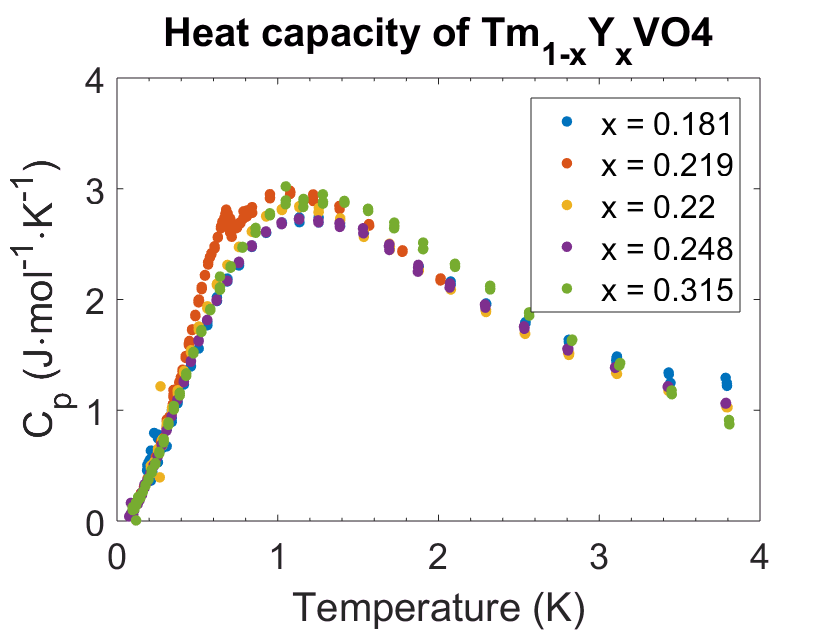

plotCpDoping(split,dpg,1,L,ttlCpY)

# Average data

## Sort each dataset by increasing value of temperature

for i=1:L
    srtd{i} = sortrows(split{i},{'T'});
%     [split{i}.T,wo] = sort(split{i}.T);
%     split{i}.Cp = split{i}.Cp(wo);
end
srtd = srtd';

## Test the temperature scattering between data points supposedly taken at the "same" temperature

4mK is the empirical maximal dispersion of data points taken consecutively at a given temperature. In order to check this, one can run the following code on the temperature variable T:

nrep = 3;% number of repetitions of the measurement at each temperature
% We want to compute the temperature separation between two data points
% that are NOT repetitions of the same measurement
Tsep = 5e-3;% value of temperature separation to be tested, in Kelvin
% Data points taken within an interval of Tsep are considered to be measured at the same temperature setpoint
for i = 1
    for k = 1:length(srtd{i}.T)-nrep
        if abs(srtd{i}.T(k+nrep)-srtd{i}.T(k))<Tsep
% if the values of temperature for two data points supposedly
% measured at two different temperature setpoints are separated by less than Tsep
            srtd{i}.T(k);% display the value of temperature for the first data point
        end
    end
end

IF this piece of code outputs one or more values AND IF these values obviously correspond to measurements that were supposed to be measured at different temperature setpoints, THEN reduce Tsep in order to reach a value for which the code does not output anything.

## Compute average of data points taken

for i = 1:L
    Tm = [];Cpm = [];stdCpm = [];% initialize temporary tables;
    k = 1;% initiliaze loop index k
    while k<length(srtd{i}.T)% loop over k
        ind = [k];% initialize temporary table of indices
        j = k+1;% initialize subloop index 
        while abs(srtd{i}.T(j)-srtd{i}.T(k))<Tsep
            % loop over datapoints within a temperature interval of Tsep
            % i.e. datapoints measured at the same temperature setpoint
            ind = [ind, j];% store index of current datapoint
            j = j+1;% increase subloop index
            if j>= length(srtd{i}.T)% safety condition
                break
            end
        end
        if length(ind)>1% do not include isolated data points
            Tm = [Tm,mean(srtd{i}.T(ind))];% average of temperature for data points
            % taken at the same temperature setpoint
            Cpm = [Cpm,mean(srtd{i}.Cpmol(ind))];% average of heat capacity
            stdCpm = [stdCpm,std(srtd{i}.Cpmol(ind))];% standard deviation of heat capacity
        end
        k = j+1;% once all datapoints measured at the same temperature setpoints are averaged,
        % increase the main loop index in order to jump to the next data point measured
        % at a different temperature setpoint
    end
    avgData(i).T = Tm;% store the full averaged temperature table
    avgData(i).Cp = Cpm;% store the full averaged heat capacity table
    avgData(i).stdCp = stdCpm;% store the full table of standard deviation of heat capacity
end

## Plot averaged Cp data for YTmVO4 x<xc

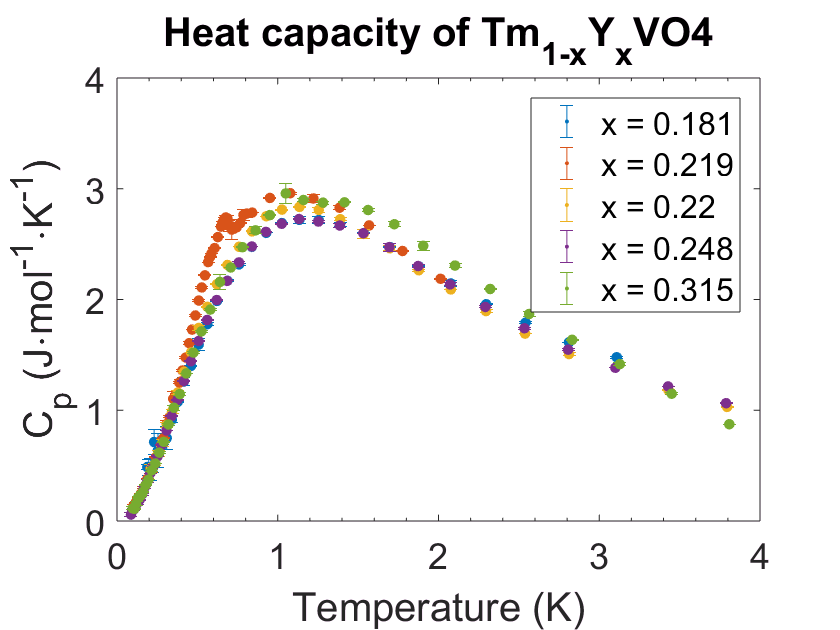

plotAvgCp(avgData,dpg,1,L)
title(ttlCpY)

# Temperature derivative of heat capacity

## Compute dCp/dT

ylbldCp = 'dC_p / dT (J\cdotmol^{-1}\cdotK^{-2})';
ttldCp = 'dC_p / dT of Tm_{1-x}Y_xVO4';
close;figure
for i=1:L
    avgData(i).dCp = diff(avgData(i).Cp)';% differential of Cp
    avgData(i).dT = diff(avgData(i).T');% differential of T
    avgData(i).Tm = mean([avgData(i).T(1:end-1);avgData(i).T(2:end)])';% in order ot have the same # of data points as in dCp
    avgData(i).derCp = avgData(i).dCp ./ avgData(i).dT;% temperature derivative of Cp
end

## Plot dCp/dT for YTmVO4

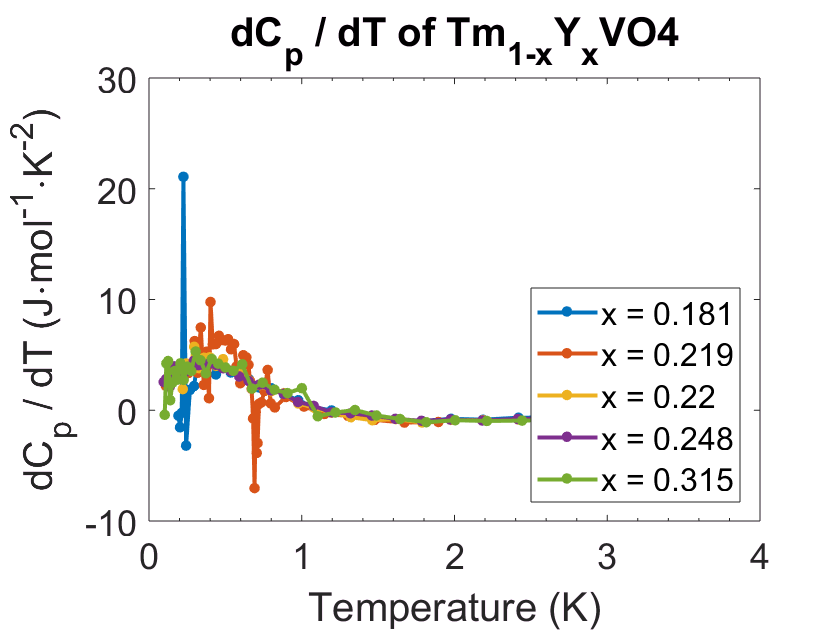

close;figure
for i=1:L
    plot(avgData(i).Tm,avgData(i).derCp,'.-','MarkerSize',18,'DisplayName',['x = ',num2str(dpg(i))])
    hold on
end
xlabel(xlblTemp);ylabel(ylbldCp);title(ttldCp);legend('show','Location','southeast');

# Fit data by temperature regimes

## Separate temperature regimes

% lowTdata(1) = IndexedStructCopy(avgData(1),(avgData(1).T<0.5));
lowTtemp = avgData(1).T(avgData(1).T<0.5);
lowTCp = avgData(1).Cp(avgData(1).T<0.5);% increases as T^1.6
highTtemp = avgData(1).T(avgData(1).T>1.6);
highTCp = avgData(1).Cp(avgData(1).T>1.6);% decreases as T^-2

# Fitting data with complex Schottky anomaly

%% Fit: 'Schottky anomaly'.
for i=1:L
    [avgData(i).xData, avgData(i).yData] = prepareCurveData(avgData(i).T,avgData(i).Cp);
end

## Single Schottky anomaly

% Set up single Schottky fittype and options.
ftsingle = fittype('b*(a/x)^2.*sech(a/x)^2', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.987660083686466 0.237061969477491];% a,b in this order
opts.Lower = [0 0];

% Fit "single Schottky" model to data.
for i=1:L
    [avgData(i).fitressingle, avgData(i).gof] = fit(avgData(i).xData, avgData(i).yData, ftsingle, opts );
    avgData(i).Coeffssingle = coeffvalues(avgData(i).fitressingle);
    disp(avgData(i).Coeffssingle)
end

    1.2332    6.9732



    1.0337    6.9827



    1.1810    7.1946



    1.2326    7.0091



    1.2658    7.4411



## Power quotient fit

% Set up normal distribution of Schottky fittype and options.
ftpower = fittype('a*x^b/(x^c+d)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1 1 1 1];% a,b,mu,sgm in this order
opts.Lower = [0 0 0 0];
% opts.Upper = [Inf Inf Inf Inf];

disp(['Coeffspower names',coeffnames(ftpower)'])

    'Coeffspower names'    'a'    'b'    'c'    'd'



% Fit normal distribution of Schottky model to data.
for i=1:L
    [avgData(i).fitrespower, avgData(i).gof] = fit( avgData(i).xData, avgData(i).yData, ftpower, opts );
    avgData(i).Coeffspower = coeffvalues(avgData(i).fitrespower);
    disp(avgData(i).Coeffspower)
end

    6.0973    1.4509    2.6533    1.2789



    3.7828    2.2368    2.9120    0.2807



    5.8376    1.5467    2.7954    1.0633



    5.7908    1.5431    2.7503    1.1345



    7.7903    1.4534    2.8979    1.6982



## Normal distribution of Schottky anomalies

% Set up normal distribution of Schottky fittype and options.
fnorm = @(T,A,g,mu,sgm) A*(g./T).^2.*sech(g./(2*T)).^2 .* normpdf(g,mu,sgm);
ftnorm = fittype(@(A,mu,sgm,T) integral(@(g)fnorm(T,A,g,mu,sgm),0,inf,'ArrayValued',true),...
    'independent', 'T', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1 1 1];% A,mu,sgm in this order
opts.Lower = [0 0 0];
% opts.Upper = [Inf Inf Inf Inf];

% Fit normal distribution of Schottky model to data.
disp(['Coeffsnorm names',coeffnames(ftnorm)'])

    'Coeffsnorm names'    'A'    'mu'    'sgm'



for i=[1,3:L]% second dataset needs additional contribution in fit
    [avgData(i).fitresnorm, avgData(i).gof] = fit(avgData(i).xData, avgData(i).yData, ftnorm, opts );
    avgData(i).Coeffsnorm = coeffvalues(avgData(i).fitresnorm);
    disp(avgData(i).Coeffsnorm)
end

    2.4284    2.3228    1.6948



    2.3531    2.3083    1.4437



    2.3161    2.3835    1.5382



    2.3923    2.4719    1.4819



## Uniform distribution of Schottky anomalies

% Set up normal distribution of Schottky fittype and options.
fschottky = @(T,A,g) A*(g./T).^2.*sech(g./(2*T)).^2;
ftunif = fittype(@(A,ti,tf,T) integral(@(g)fschottky(T,A,g),ti,tf,'ArrayValued',true),...
    'independent', 'T', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1 0 2];% A,mu,sgm in this order
opts.Lower = [0 0 0];
% opts.Upper = [Inf Inf Inf Inf];

% Fit normal distribution of Schottky model to data.
disp(['Coeffsunif names',coeffnames(ftunif)'])

    'Coeffsunif names'    'A'    'ti'    'tf'



for i=[1,3:L]% second dataset needs additional contribution in fit
    [avgData(i).fitresunif, avgData(i).gof] = fit(avgData(i).xData, avgData(i).yData, ftunif, opts );
    avgData(i).Coeffsunif = coeffvalues(avgData(i).fitresunif);
    disp(avgData(i).Coeffsunif)
end

    0.4907    0.4610    4.7974



    0.5497    0.5895    4.4608



    0.5007    0.5059    4.7179



    0.5258    0.5518    4.7754



## Plot data + fits

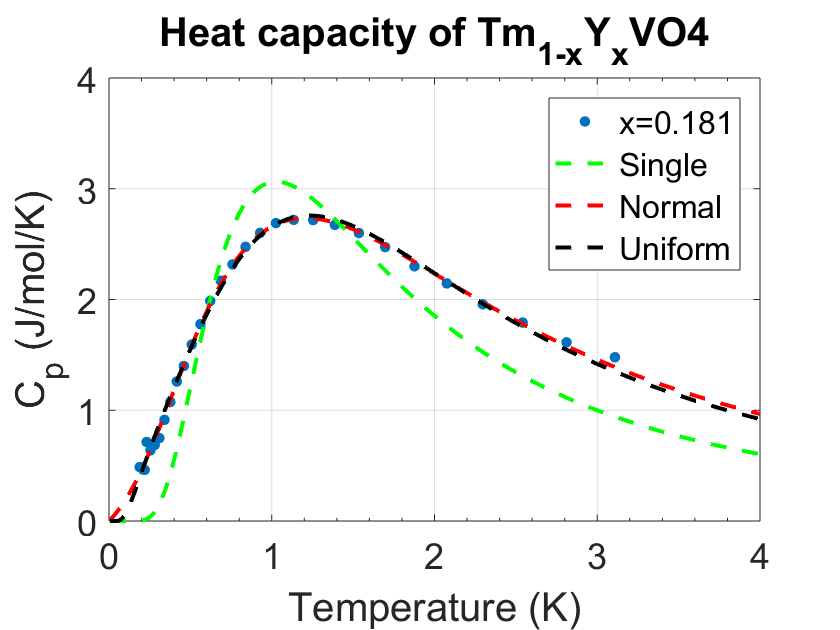

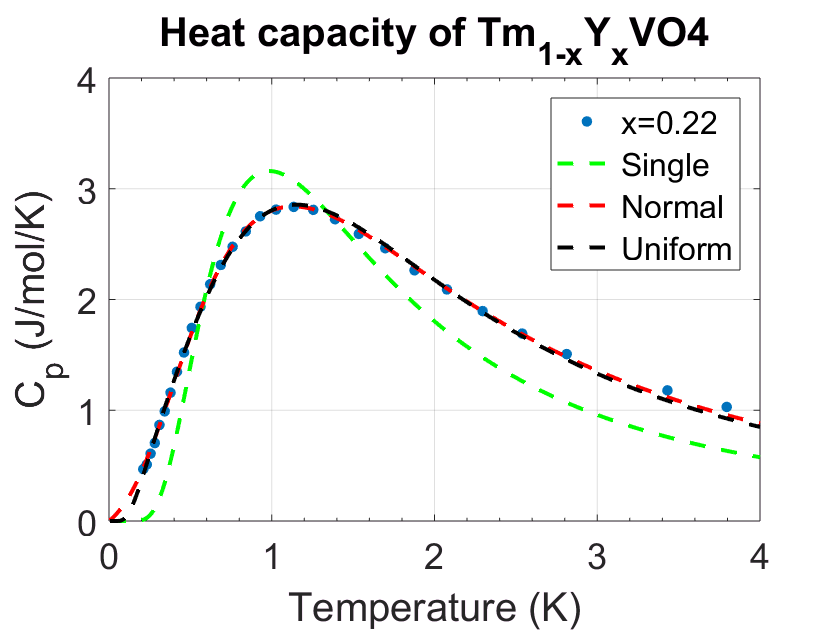

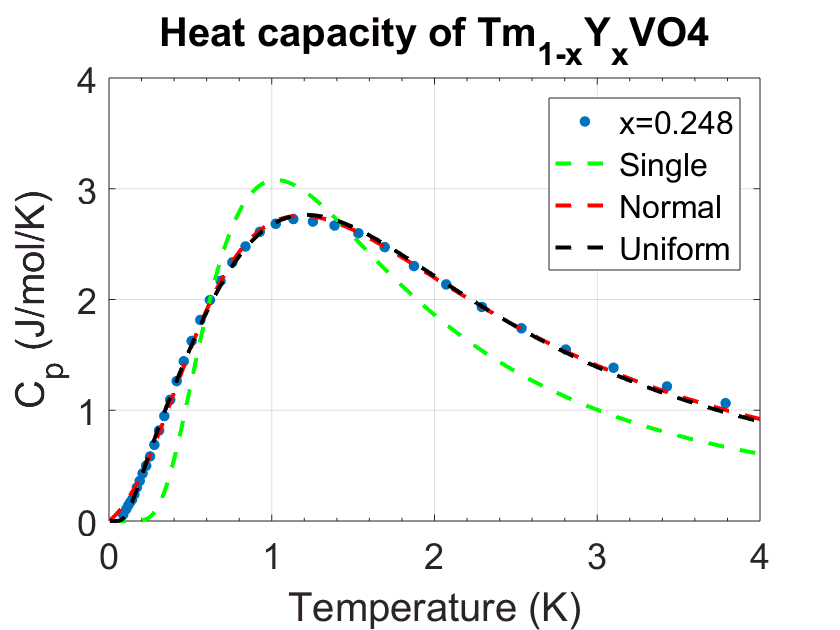

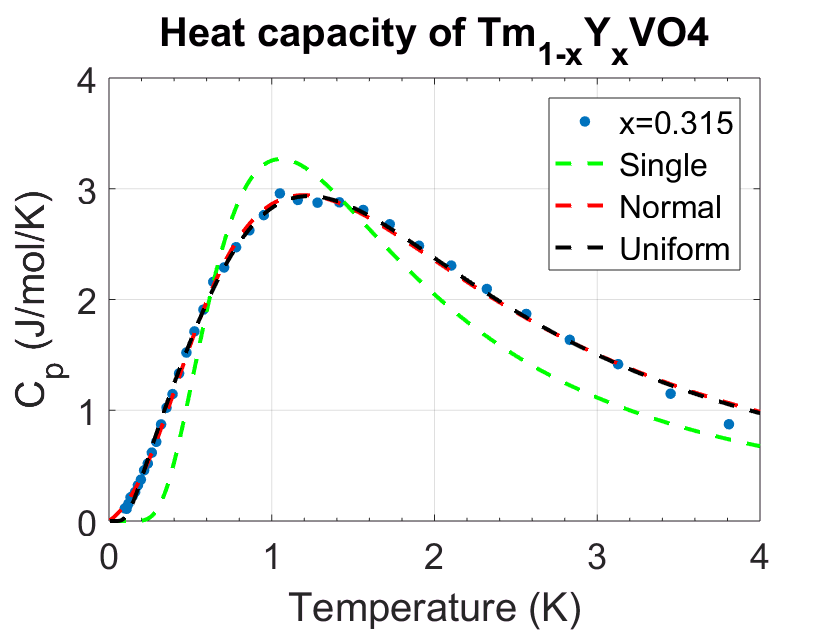

for i=[1,3:L]
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).xData, avgData(i).yData,'.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p1 = plot(avgData(i).fitressingle,'--g');%,'DisplayName','Single');
    p2 = plot(avgData(i).fitresnorm,'--r');%,'DisplayName','Normal');
    p3 = plot(avgData(i).fitresunif,'--k');%,'DisplayName','Normal');
    % plot(fitresnorm2,'--k');
    % plot(fitrespower,'--k','DisplayName','power');
    % p4 = plot(fitrespower,'--r');
    % legend('show');
    title('Heat capacity of Tm_{1-x}Y_xVO4')
    legend([p0,p1,p2,p3],{['x=',num2str(dpg(i))],'Single','Normal','Uniform'});
    % Label axes
    xlabel('Temperature (K)');ylabel('C_p (J/mol/K)');grid on
end

## Only for x=0.219: fit with normal distribution + linear contribution between 0.4K and 0.69K

ftnormlin = fittype(@(A,B,mu,sgm,T) integral(@(g)fnorm(T,A,g,mu,sgm),0,inf,'ArrayValued',true)+B*(T-0.4).*heaviside(T-0.4).*heaviside(0.69-T),...
    'independent', 'T', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1 1 1 1];% A,mu,sgm in this order
opts.Lower = [0 0 0 0];
% opts.Upper = [Inf Inf Inf Inf];

disp(['Coeffspower names',coeffnames(ftpower)'])

    'Coeffspower names'    'a'    'b'    'c'    'd'



% Fit normal distribution of Schottky model to data.
for i=2% second dataset needs additional contribution in fit
    [avgData(i).fitresnorm, avgData(i).gof] = fit(avgData(i).xData, avgData(i).yData, ftnormlin, opts );
    avgData(i).Coeffsnorm = coeffvalues(avgData(i).fitresnorm);
    disp(avgData(i).Coeffsnorm)
end

    2.3199    1.0052    2.2856    1.2025



## Only for x=0.219: uniform distribution + linear contribution between 0.4K and 0.69K

% Set up normal distribution of Schottky fittype and options.
fschottky = @(T,A,g) A*(g./T).^2.*sech(g./(2*T)).^2;
ftunif = fittype(@(A,B,ti,tf,T) integral(@(g)fschottky(T,A,g),ti,tf,'ArrayValued',true)+B*(T-0.4).*heaviside(T-0.4).*heaviside(0.69-T),...
    'independent', 'T', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [1 1 0 2];% A,mu,sgm in this order
opts.Lower = [0 0 0 0];
% opts.Upper = [Inf Inf Inf Inf];

% Fit normal distribution of Schottky model to data.
disp(['Coeffsunif names',coeffnames(ftunif)'])

    'Coeffsunif names'    'A'    'B'    'ti'    'tf'



for i=2% second dataset needs additional contribution in fit
    [avgData(i).fitresunif, avgData(i).gof] = fit(avgData(i).xData, avgData(i).yData, ftunif, opts );
    avgData(i).Coeffsunif = coeffvalues(avgData(i).fitresunif);
    disp(avgData(i).Coeffsunif)
end

    0.6254    1.0439    0.6704    4.1676



## Only for x=0.219: plot data + fit

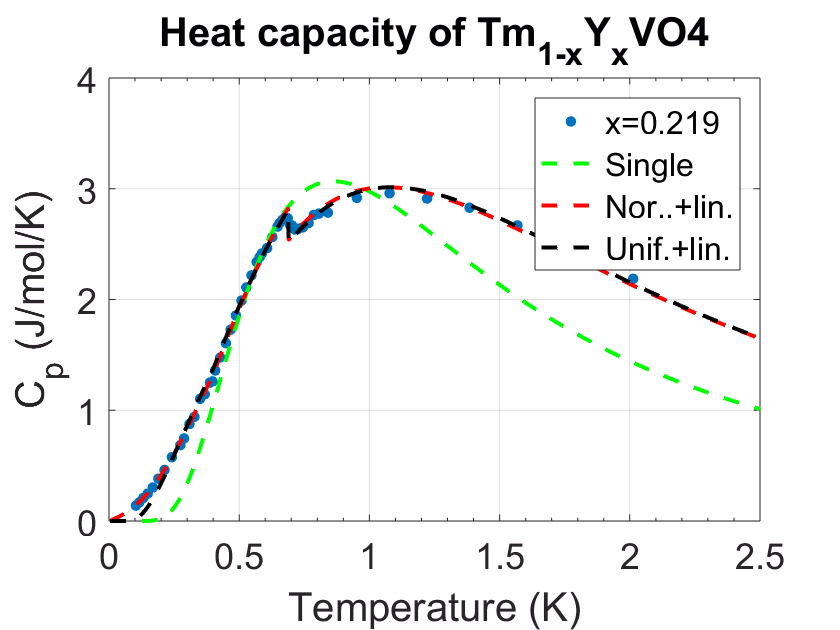

for i=2
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).xData, avgData(i).yData,'.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p1 = plot(avgData(i).fitressingle,'--g');%,'DisplayName','Single');
    p2 = plot(avgData(i).fitresnorm,'--r');%,'DisplayName','Normal');
    p3 = plot(avgData(i).fitresunif,'--k');%,'DisplayName','Normal');
    title('Heat capacity of Tm_{1-x}Y_xVO4')
    legend([p0,p1,p2,p3],{['x=',num2str(dpg(i))],'Single','Nor..+lin.','Unif.+lin.'});
    % Label axes
    xlabel('Temperature (K)');ylabel('C_p (J/mol/K)');grid on
end

## Plot the normal distributions of transverse fields for each doping level

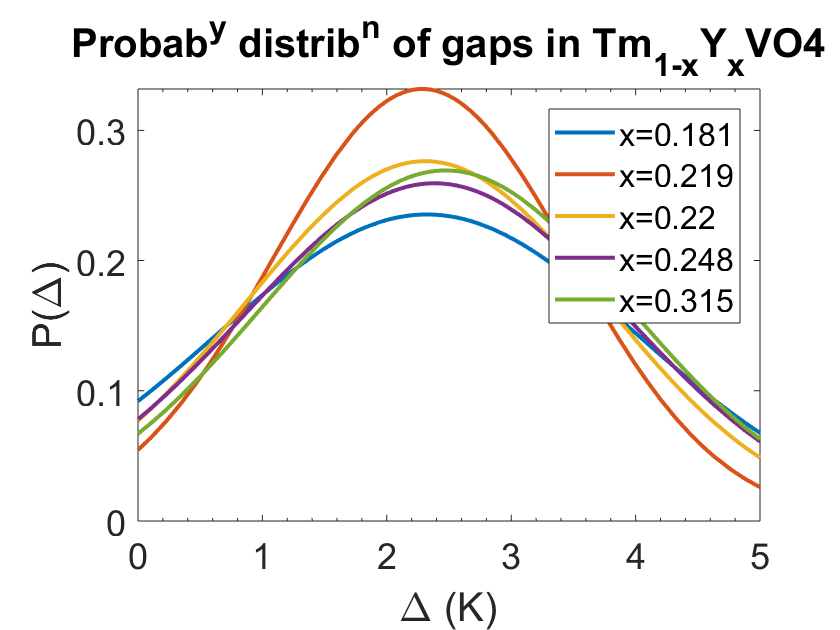

close; figure
for i=1:L
    fplot(@(x) normpdf(x,avgData(i).fitresnorm.mu,avgData(i).fitresnorm.sgm),...
        'LineWidth',2,'DisplayName',['x=',num2str(dpg(i))])
    hold on
end
xlim([0 5]);
title('Probab^{y} distrib^{n} of gaps in Tm_{1-x}Y_xVO4')
xlabel('\Delta (K)');ylabel('P(\Delta)');legend('show')

## Plot the fitting parameter mu of the normal distributions as a function of doping

mu is the center of the normal distributions of transverse fields

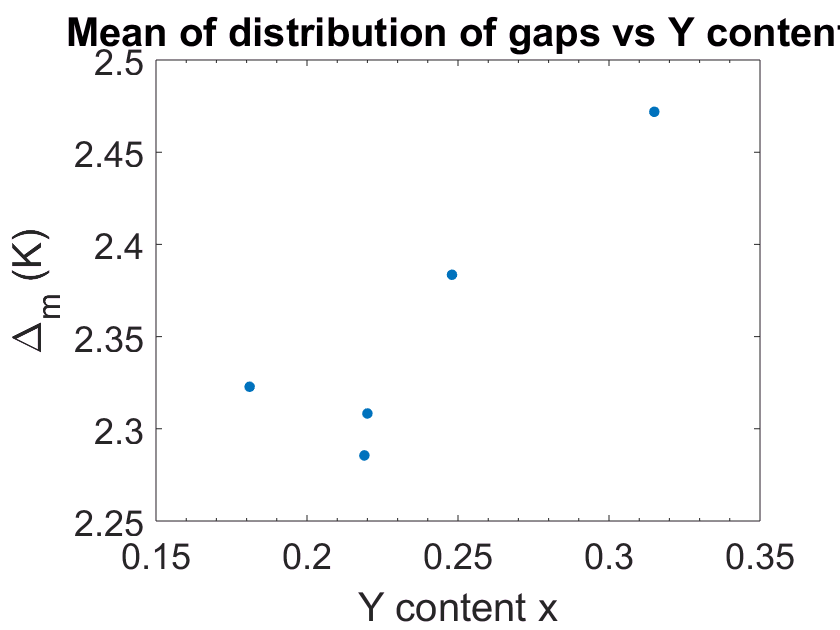

mu = zeros(L,1);
close;figure
for i=1:L
    mu(i) = avgData(i).fitresnorm.mu;
end
plot(dpg,mu,'.');
hold on
% plot(dpg(2),mu(2),'or');
xlabel('Y content x');
ylabel('\Delta_m (K)');
title('Mean of distribution of gaps vs Y content');

## Plot the fitting parameter sgm of the normal distributions as a function of doping

sgm is the width of the normal distributions of transverse fields

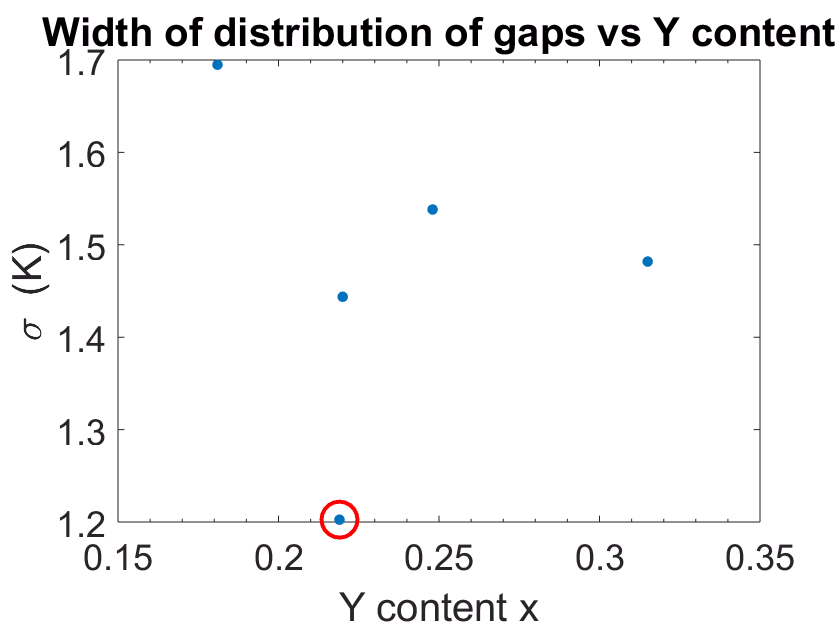

sgm = zeros(L,1);
close;figure
for i=1:L
    sgm(i) = avgData(i).fitresnorm.sgm;
end
plot(dpg,sgm,'.');
hold on
% plot(dpg(2),sgm(2),'or');
xlabel('Y content x');ylabel('\sigma  (K)');
title('Width of distribution of gaps vs Y content');